## linclassdemo - Linear classifier demo

Implementation of a simple, hand-designed linear classif�er

*Hand-designed* means that we don't learn anything from the data, we just "invent" a reasonable classifier and see if it works.

First off, clear workspace (the memory of all variables):

clear

Create a "toy" training set with 10 random points within the square `[1,2]x[1,2]` (as class 1) and 10 points in `[0,1]x[0,1]` (as class 0)

x = 1+rand(10,2);
x = [ x ; rand(10,2)]

x =     1.5449    1.5824
    1.6862    1.0707
    1.8936    1.9227
    1.0548    1.8004
    1.3037    1.2859
    1.0462    1.5437
    1.1955    1.9848
    1.7202    1.7157
    1.7218    1.8390
    1.8778    1.4333


Create corresponding vector of targets

t = [ones(10,1);zeros(10,1)];

Plot data

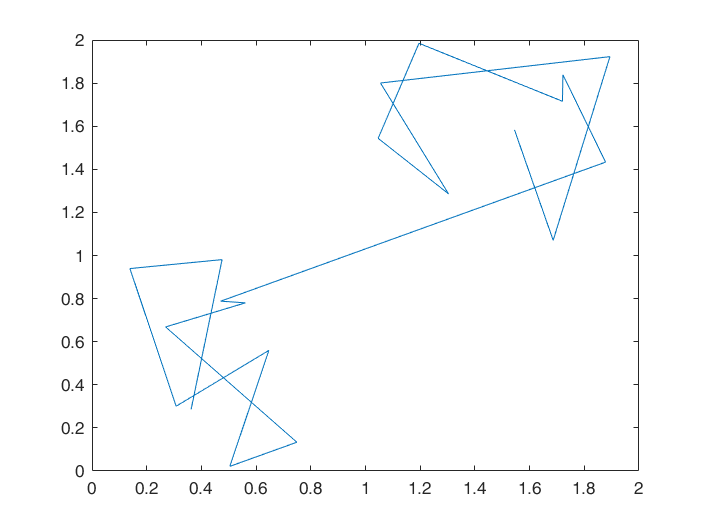

plot(x(:,1),x(:,2))

not very clear; plot again with suitable style (point markers rather than connecting lines) and different colors for different classes...

Plot class 1 in blue crosses:

plot(x(t==1,1),x(t==1,2),'xb'); 

(note indexing with logical expression)

Don’t replace figure, add next plots over old one:

hold on

Plot class 0 in red circles:

plot(x(t==0,1),x(t==0,2),'or');

Make sure that axes cover the full possible range;

axis([0 2 0 2])

Add grid:

grid on 

Add figure title;

title('Demo data')

Add axis labels:

xlabel('Feature 1')
ylabel('Feature 2') 

Adding plots to the figure is not necessary anymore, so:

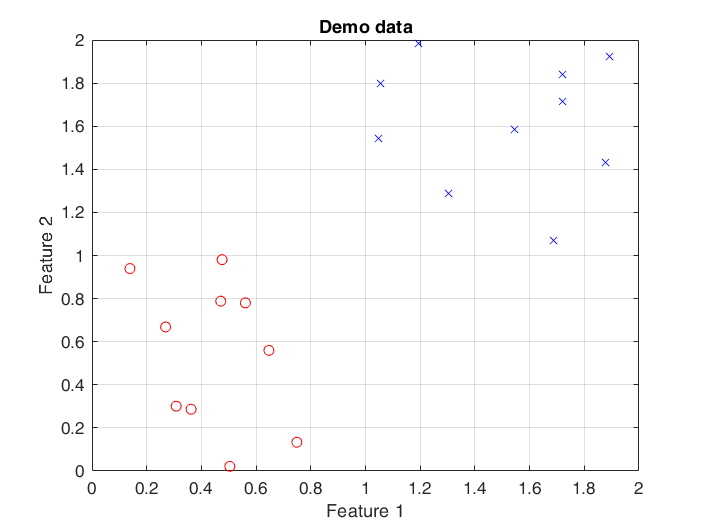

hold off

Let’s try classifying with this hyperplane (actually, a line):

w = [1 1];
y = x*w'>0;  % classification

Display the number of correctly classified points:

disp(sum(y==t))

    10


...not satisfactory. Let's plot the data with the classification obtained rather than with the correct labels:

plot(x(y==1,1),x(y==1,2),'xb'); 
hold on
plot(x(y==0,1),x(y==0,2),'or');
axis([-2 2 -2 2])
grid on 
title('Demo data, obtained classification')
xlabel('Feature 1')
ylabel('Feature 2') 

Let's also plot the hyperplane:

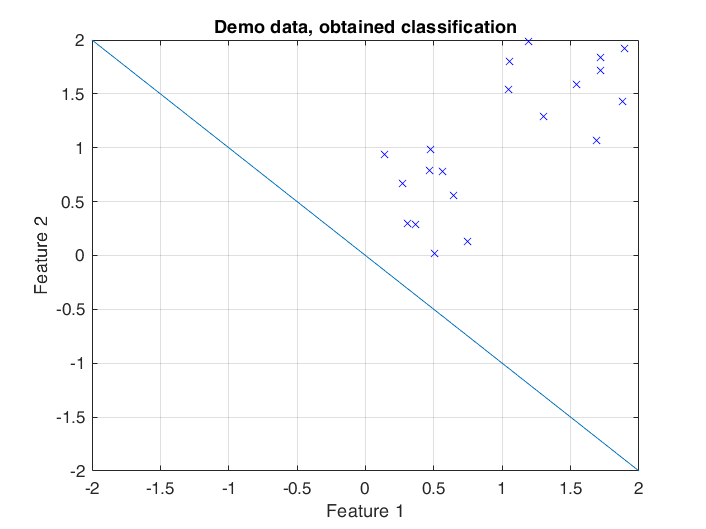

xraster = -2:.1:2;
plot(xraster, -xraster*w(1)/w(2))
hold off

A bit of geometrical reasoning tells us that we need one more parameter in the hyperplane, otherwise it will always cross the origin and the figure shows that this is not ok.

Let’s add a column of all ones to the training set

xx = [ones(size(x,1),1) x];

The coefficient corresponding to the constant column will be the constant offset in the equation of the hyperplane

ww = [-2 1 1];

Let’s classify with this hyperplane:

yy=linclass(xx,ww);

This time we use an external function to encapsulate the classifier, however simple it may be. See file `linclass.m`

Display the result using a more sophisticated printing function:

fprintf('number of correct classifications: %i out of %i total observations\n', ...
sum(yy==t), size(yy,1))

number of correct classifications: 20 out of 20 total observations


Much better now. Let's see the new hyperplane in context:

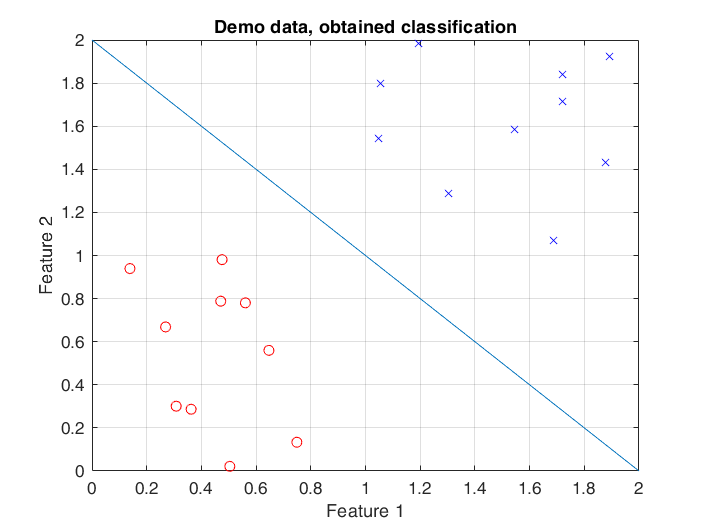

plot(xx(yy==1,2),xx(yy==1,3),'xb'); 
hold on
plot(xx(yy==0,2),xx(yy==0,3),'or');
axis([0 2 0 2])
grid on 
title('Demo data, obtained classification')
xlabel('Feature 1')
ylabel('Feature 2') 
xraster = 0:.1:2;
plot(xraster, -xraster.*ww(2)/ww(3)-ww(1))
hold off